# Example

The uniform-shear model is computed with the parameters used in Mann

(1998) [1] and compared to the spectra from the Great belt experiment, which are displayed in Mann (1994)

The three parameters of the uniform-shear model are:

- $\alpha \epsilon^{2/3}$, referred to as "alphaEps" 

- $\Gamma$, referred to as "GAMMA"

- $L$, referred to as "L"

References:

[1] Mann, J. (1994). The spatial structure of neutral atmospheric surface-layer turbulence. *Journal of fluid mechanics*, *273*, 141-168.

## INITIALISATION


% Basic parameters definitions
clearvars;close all;clc;
U = 22.3; % Mean wind speed (m/s)
z = 70; % altitude (m)
GAMMA = 3.2; % Shear parameter
L = 61; % m
alphaEps =0.11; % m^(4/3)/s^2

% frequency steps
N1=100; % number of frequency step for the wavevector component  k1
k2max = log10(100); % maximal value of the wavevector component k2
k3max = log10(100);
k2min = -6; %minimal  value of k2
k3min = -6;
% frequency vector
f = logspace(log10(1/3600),log10(10),N1);
%wavenumber
k1 = 2*pi.*f./U;


## Computation of the uniform shear model



% Compute Mann spectral tensor
tic
[PHI,k2,k3,k11,k2_log,k3_log] = MannTurb(alphaEps,GAMMA,L,'N1',N1,'N2',100,'N3',100,'k2max',k2max,'k3max',k3max,'k2min',k2min ,'k3min',k3min);
toc

Elapsed time is 4.316171 seconds.



%% Compute the corresponding single point spectra
FM= squeeze(trapz(k3_log,trapz(k2_log,PHI,2),3));
% One-sided single point spectra is chosen
FM = FM(end-N1+1:end,:,:);

% set Suv = 0 and Svw = 0
FM(:,1,2)=0; FM(:,2,1)=0; FM(:,2,3)=0; FM(:,3,2)=0;



## Comparison with the wind spectra from the great belt bridge experiment

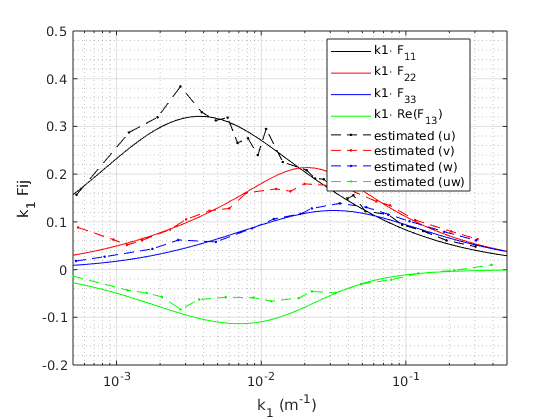

% estimated from Mann (1994) with a digitalization software, so the resolution is not perfect
load('GreatBeltSpectra.mat') 

clf;close all;
figure
hold on;box on;
plot(k11,k11'.*FM(:,1,1),'k',k11,k11'.*FM(:,2,2),'r',k11,k11'.*FM(:,3,3),'b',k11,k11'.*FM(:,1,3),'g');
plot(fu1,Su1,'k.--',fv1,Sv1,'r.--',fw1,Sw1,'b.--',fuw1,Suw1,'g.--')
legend('k1\cdot F_{11}','k1\cdot F_{22}','k1\cdot F_{33}',...
    'k1\cdot Re(F_{13})','estimated (u)','estimated (v)','estimated (w)','estimated (uw)','location','best')
set(gca,'Xscale','log')
ylim([-0.2,0.5])
xlim([0.0005,0.5])
xlabel('k_{1} (m^{-1}) ')
ylabel('k_{1} Fij');
grid on
grid minor

set(gcf,'color','w')



## Coherence

Warning: Due to the particular numerical implementation, there exist potentialy large numerical errors at high frequency, which have been put as "nan" in the present code.

### Lateral separations

dy = 15; % lateral separation (m)
dz = 0; % vertical separation (m)

tic
[newK1,cocoh,quadcoh] = MannCoherence(PHI,k11,k2,k3,dy,dz,k2_log,k3_log);
toc

Elapsed time is 8.035514 seconds.


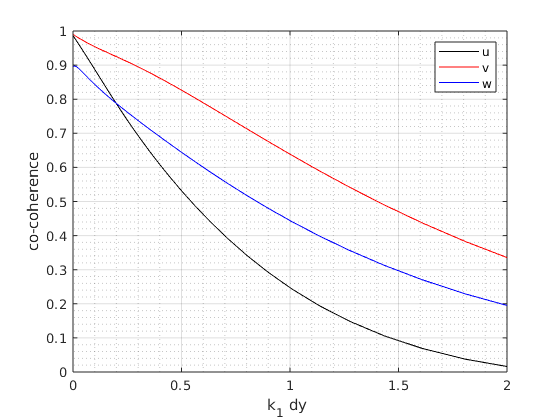

quadcoh(quadcoh<1e-6)=0;

figure
hold on;box on;
plot(newK1.*dy,squeeze(cocoh(1,1,:)),'k',newK1.*dy,squeeze(cocoh(2,2,:)),'r',newK1.*dy,squeeze(cocoh(3,3,:)),'b')
xlabel('k_{1} dy ')
ylabel('co-coherence');
legend('u','v','w')
grid on
grid minor
set(gcf,'color','w')
xlim([0,2])

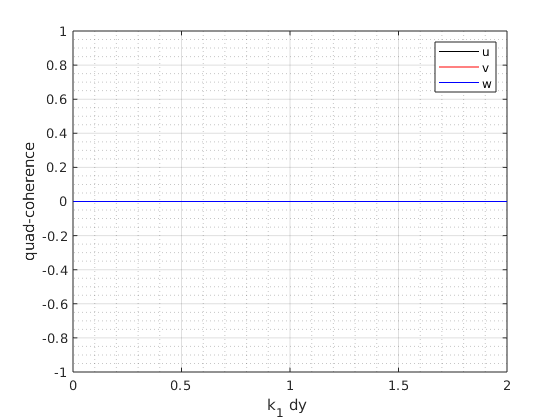


figure
hold on;box on;
plot(newK1.*dy,squeeze(quadcoh(1,1,:)),'k',newK1.*dy,squeeze(quadcoh(2,2,:)),'r',newK1.*dy,squeeze(quadcoh(3,3,:)),'b')
xlabel('k_{1} dy ')
ylabel('quad-coherence');
legend('u','v','w')
grid on
grid minor
set(gcf,'color','w')
xlim([0,2])

### Vertical separations

dy = 0; % lateral separation (m)
dz = 15; % vertical separation (m)

tic
[newK1,cocoh,quadcoh] = MannCoherence(PHI,k11,k2,k3,dy,dz,k2_log,k3_log);
toc

Elapsed time is 7.827397 seconds.


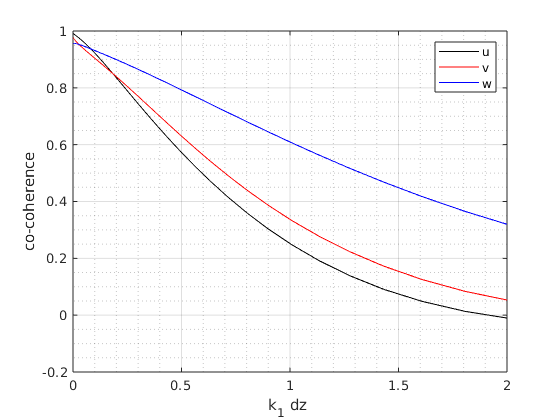

quadcoh(quadcoh<1e-6)=0;

figure
hold on;box on;
plot(newK1.*dz,squeeze(cocoh(1,1,:)),'k',newK1.*dz,squeeze(cocoh(2,2,:)),'r',newK1.*dz,squeeze(cocoh(3,3,:)),'b')
xlabel('k_{1} dz ')
ylabel('co-coherence');
legend('u','v','w')
grid on
grid minor
set(gcf,'color','w')
xlim([0,2])

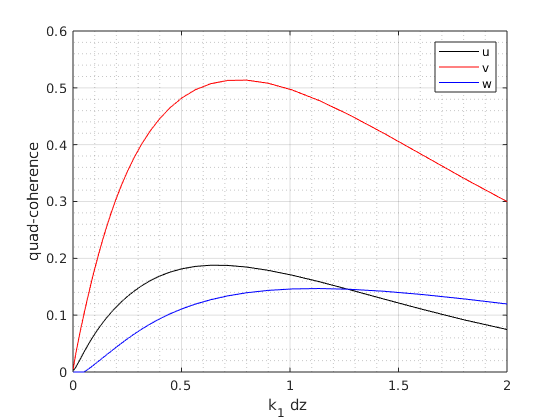


figure
hold on;box on;
plot(newK1.*dz,squeeze(quadcoh(1,1,:)),'k',newK1.*dz,squeeze(quadcoh(2,2,:)),'r',newK1.*dz,squeeze(quadcoh(3,3,:)),'b')
xlabel('k_{1} dz ')
ylabel('quad-coherence');
legend('u','v','w')
grid on
grid minor
set(gcf,'color','w')
xlim([0,2])